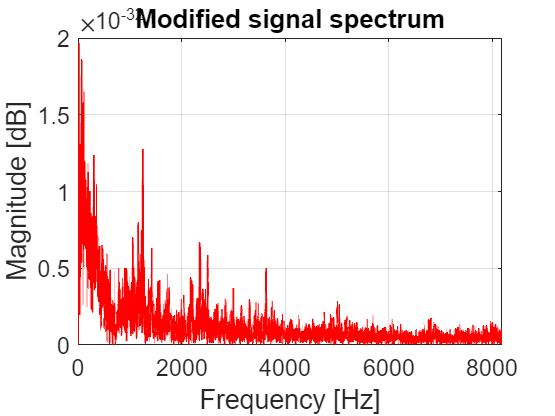

fid = fopen('adc_buffer_enable.bin'); % file should be in the working directory
data = fread(fid,inf,'float'); % put 'float' instead of int if your data is float type.
fclose(fid);

[freq spectrum]=calculateFFT(data,16384);

figure; 
plot(freq,spectrum,'r','LineWidth',1);

set(gca,'FontSize',14)
grid on;
xlim([0 8192]); % limit the view for freq axis
xlabel('Frequency [Hz]','FontSize',16);
ylabel('Magnitude [dB]','FontSize',16);  
title('Modified signal spectrum');  % This is the title of the plot (modify for each different plot)